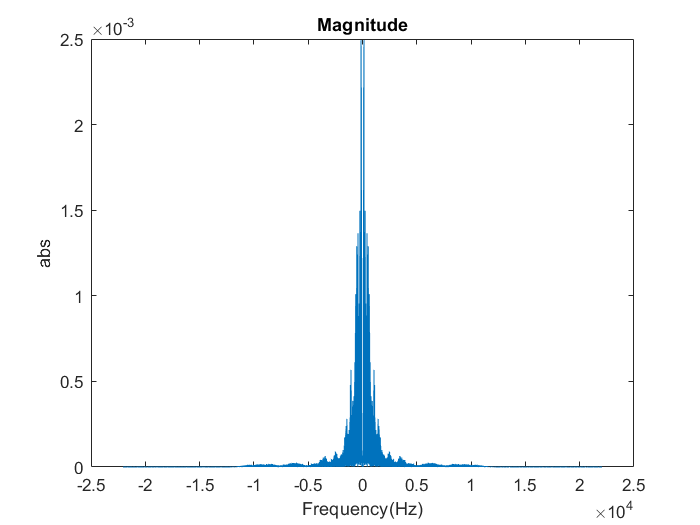

[x,Fs]=audioread('sample.wav');
x=x(:,1);
n = length(x);     
Fourier_x=fft(x)/n;
fshift = (-Fs/2:Fs/(n-1):Fs/2);
shifted_x=fftshift(Fourier_x);
plot(fshift,abs(shifted_x))
title('Magnitude')
xlabel('Frequency(Hz)')
ylabel('abs')

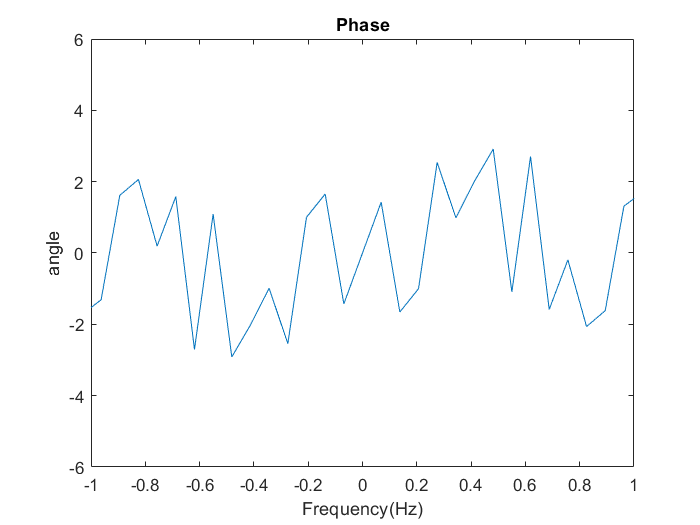

figure
plot(fshift,angle(shifted_x))
axis([-1 1 -6 6])
title('Phase')
xlabel('Frequency(Hz)')
ylabel('angle')

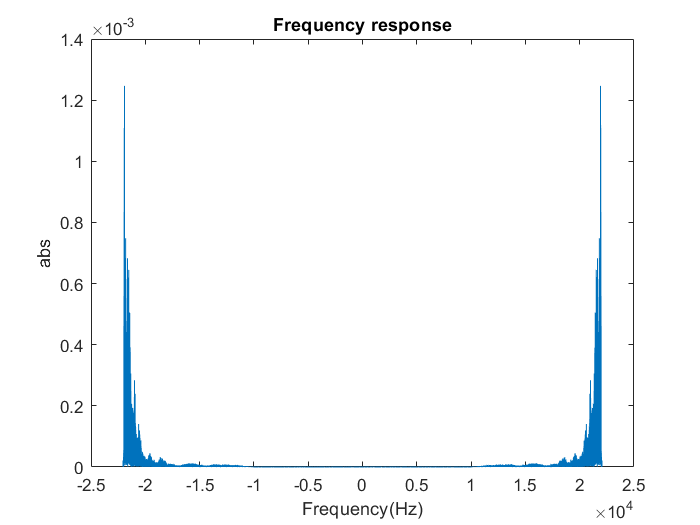


f=(-Fs/2:Fs/(n-1):Fs/2);

H=0.5*exp(-0.4*pi*f*1i);

Magnitude=abs(H);
Phase=angle(H);

F_response=H.*Fourier_x.';


plot(f,abs(F_response))
title('Frequency response')
xlabel('Frequency(Hz)')
ylabel('abs')

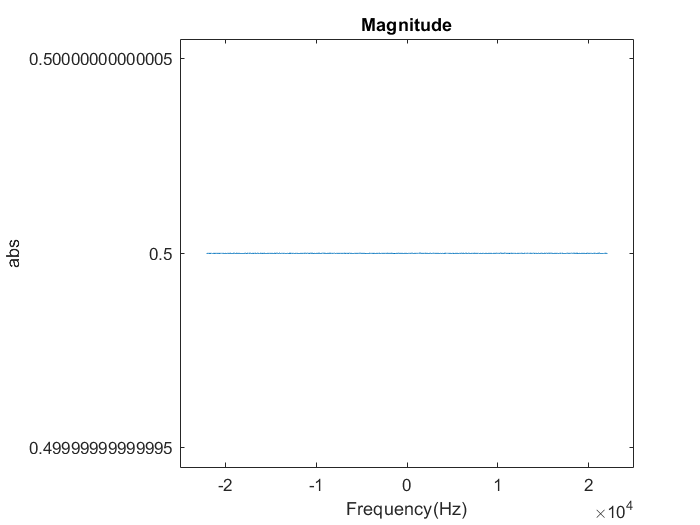

figure

plot(f,Magnitude)
title('Magnitude')
xlabel('Frequency(Hz)')
ylabel('abs')

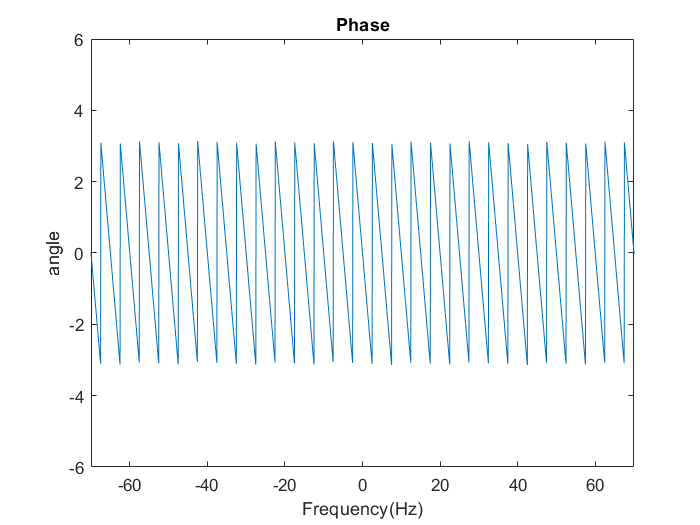

figure
plot(f,Phase)
axis([-70 70 -6 6])
title('Phase')
xlabel('Frequency(Hz)')
ylabel('angle')


f = (0:Fs/(n-1):Fs);

H1=1+0.5*exp(-0.4*pi*f*1i);

t1=(0:n-1)*(100/n);
Yf=(H1.').*(Fourier_x);


Yt=n*ifft(Yf);

plot(t1,Yt')

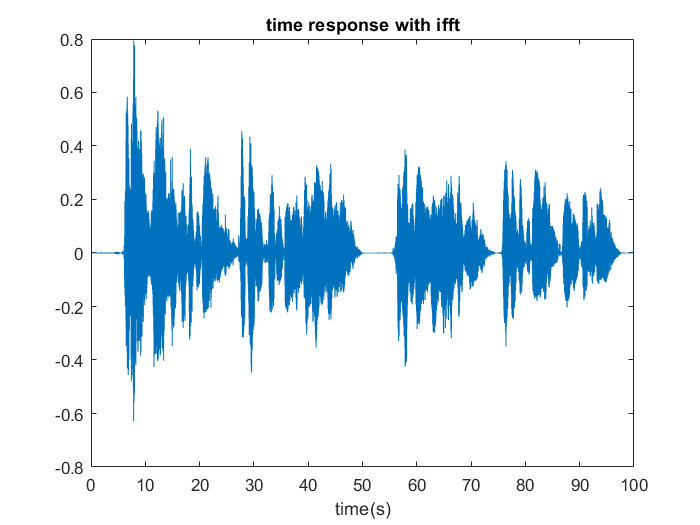

title('time response with ifft')
xlabel('time(s)')

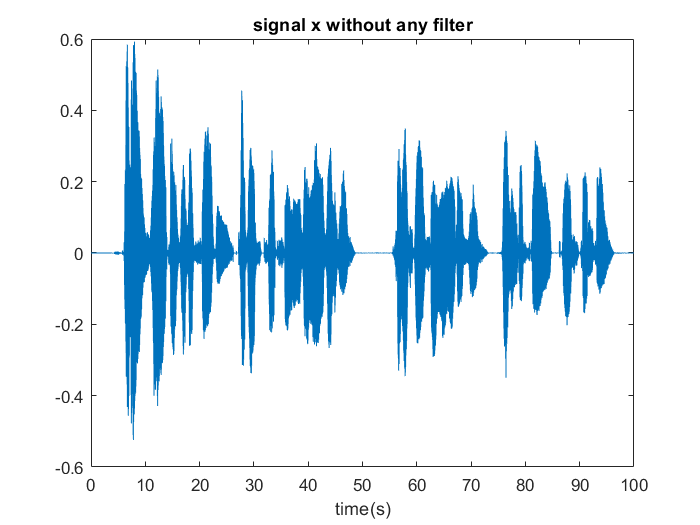


figure
plot(t1,x.')
title('signal x without any filter')
xlabel('time(s)')


sound(real(Yt),Fs)

audiowrite('new.wav',real(Yt),Fs)




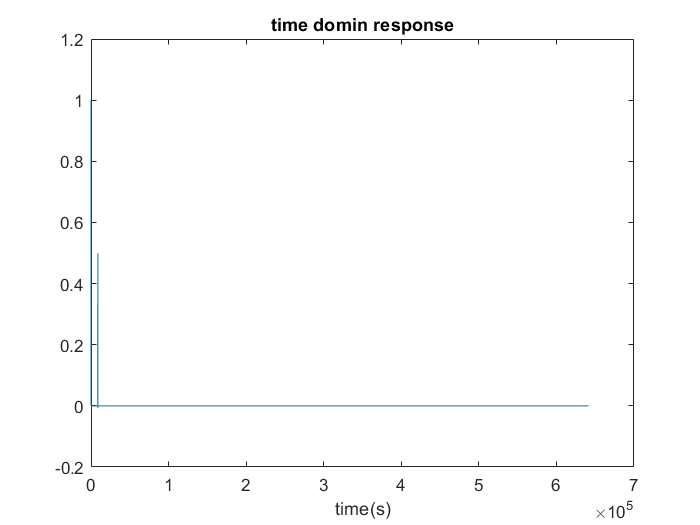

t=(0:n-1)/Fs;
f = (0:Fs/(n-1):Fs);

H1=1+0.5*exp(-0.4*pi*f*1i);

h=ifft(H1);
plot(real(h))
title('time domin response')
xlabel('time(s)')

z=conv(x,h.');

figure

plot(t,z(1:641279))

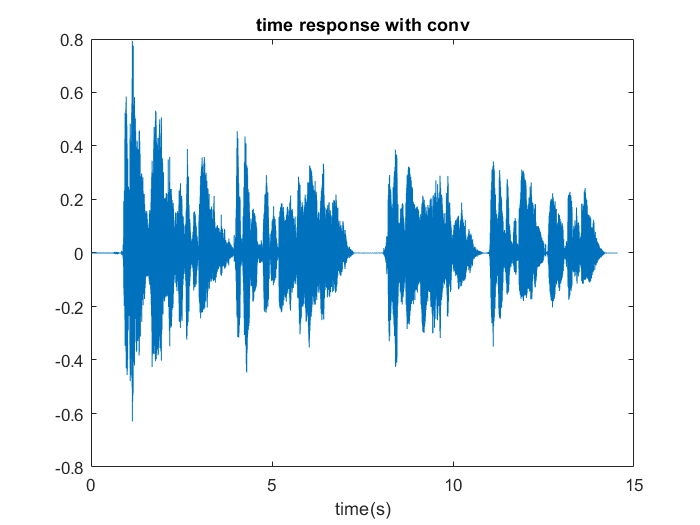

title('time response with conv')
xlabel('time(s)')

figure
plot(t,Yt)

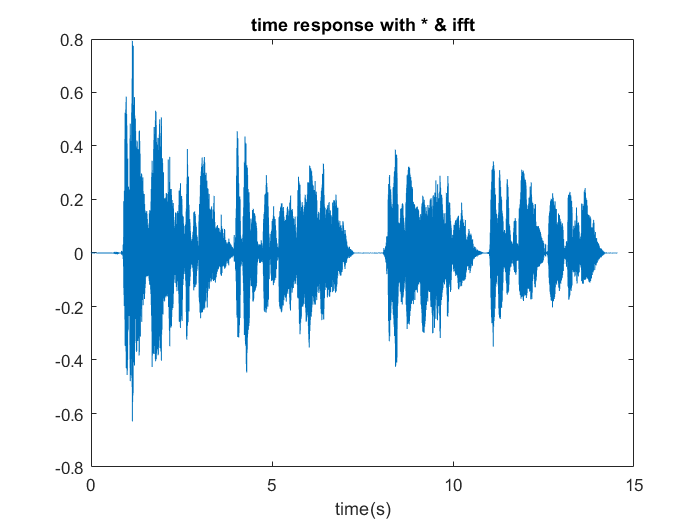

title('time response with * & ifft')
xlabel('time(s)')

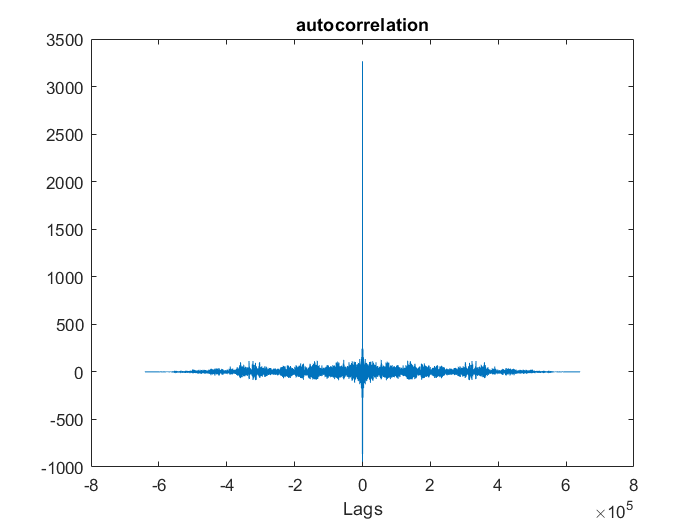


[autocorrelation_x,time]=xcorr(x.');
[correlation_yx,time1]=xcorr(Yt,x.');

t=(0:n-1)/Fs;

plot(time,autocorrelation_x)
title('autocorrelation')
xlabel('Lags')

figure
plot(time1,correlation_yx)

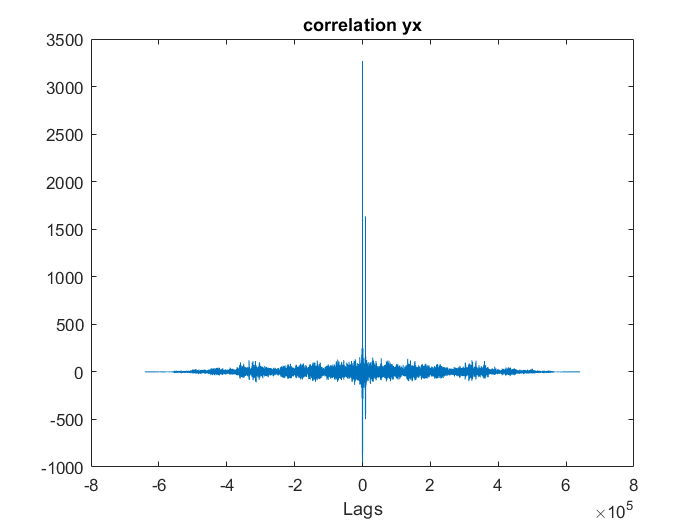

title('correlation yx')
xlabel('Lags')

t=(0:n-1)/Fs;
t1=(0:1/3:n-1)/Fs;
L=length(H1)

L = 641279

f=(-Fs/2:Fs/(n-1):Fs/2);
RHS=conv(autocorrelation_x,h);

[autocorrelation_y,lag]=xcorr(Yt);

Gy=fft(autocorrelation_y(1:641279))/L;
Gx=fft(autocorrelation_x(1:641279))/L;

compare_result=Gx.*(abs(H1).^2);

%compare part a

plot(time1,correlation_yx)

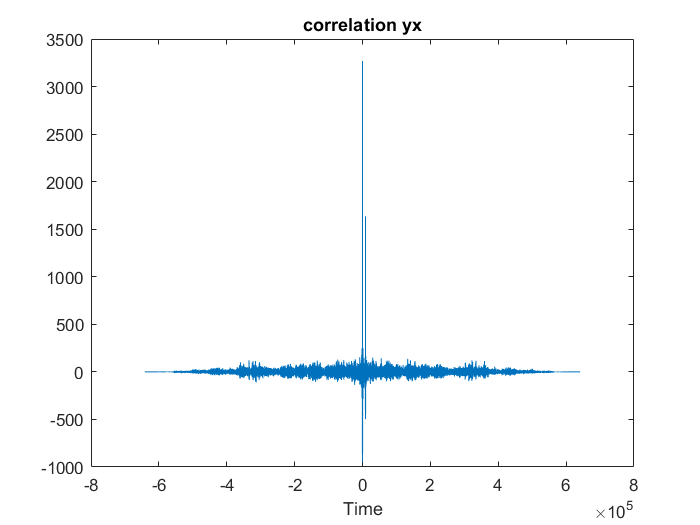

title('correlation yx')
xlabel('Time')

figure
plot(time1,RHS(1:1282557))

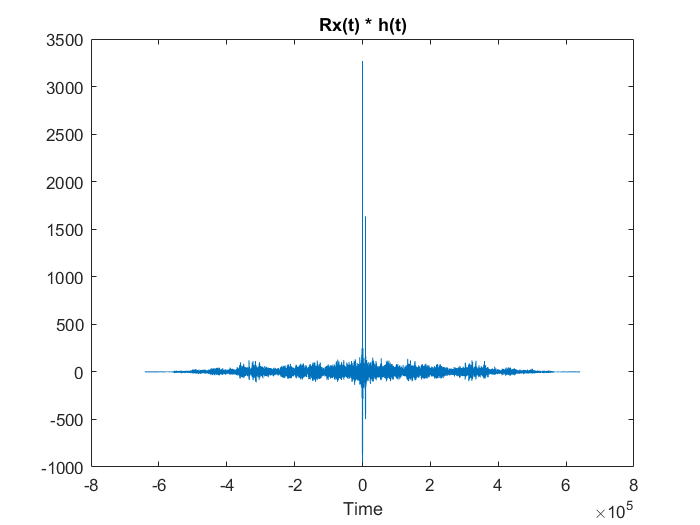

title('Rx(t) * h(t)')
xlabel('Time')


err1=immse(correlation_yx.',RHS(1:1282557))

err1 = 1.0148e-05

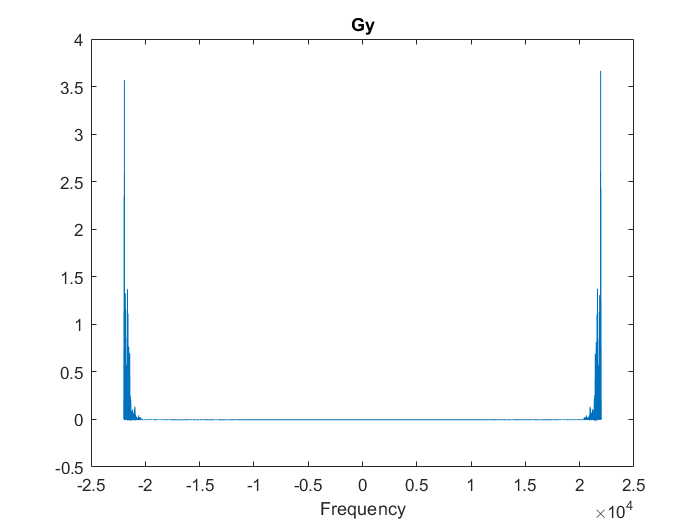



%compare part b

figure
plot(f,real(Gy))
title('Gy')
xlabel('Frequency')

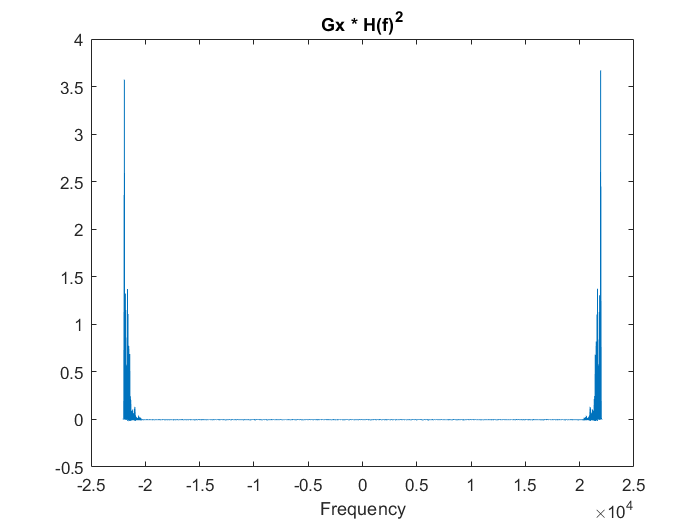

figure
plot(f,real(compare_result))
title('Gx * H(f)^2')
xlabel('Frequency')


err2=immse( Gy.' ,compare_result)

err2 = 4.0167e-04

[x,Fs]=audioread('sample.wav');

x=x(:,1);

n = length(x);     

Fourier_x=fft(x)/n;

f = (0:Fs/(n-1):Fs);

H_Making_echo=1+0.5*exp(-0.4*pi*f*1i)+0.3*exp(-0.2*pi*f*1i);

Y_final=(H_Making_echo.').*Fourier_x;


v=n*ifft(Y_final);

sound(real(v),Fs)

audiowrite('echoed.wav',real(v),Fs)

[correlation_vx,baze]=xcorr(v,x);

plot(baze,correlation_vx)

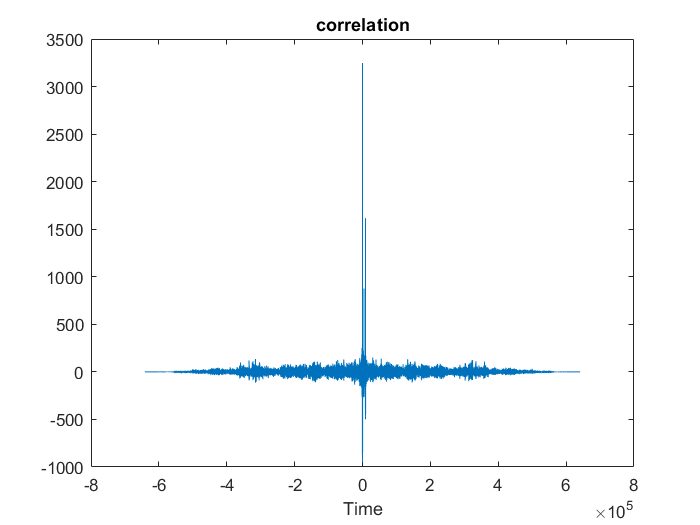

title('correlation')
xlabel('Time')